**Ejemplo de aplicación de filtros adaptativos utilizando el algoritmo LMS**

Se crea una señal de tiempo discreto, para este ejemplo una señal periodica que combina 3 armónicos

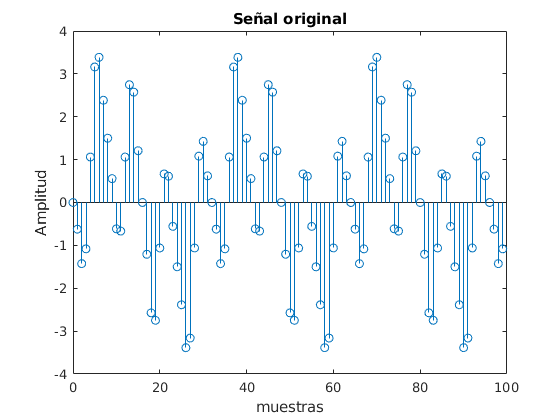

N=10000;
n=0:N-1;
xn=0.5*sin(2*pi*n*1/4)-2*sin(2*pi*n*1/8)+1.5*sin(2*pi*n*1/32);
figure()
stem(n(1:100),xn(1:100)) %se grafican 100 muestras
xlabel('muestras')
ylabel('Amplitud')
title('Señal original')

Se agrega ruido a la señal original

factor_ruido=0.05

factor_ruido = 0.0500

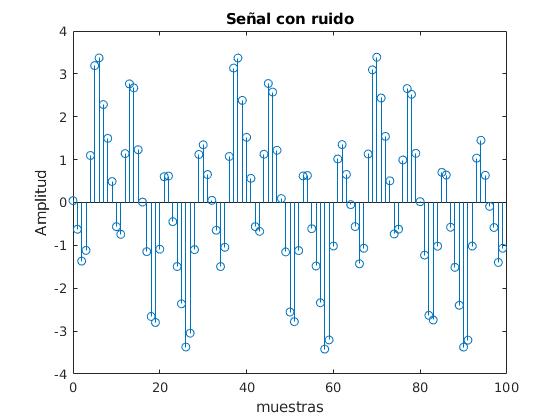

xnr = xn + randn(1,N).*factor_ruido;
figure()
stem(n(1:100),xnr(1:100)) %se grafican 100 muestras
xlabel('muestras')
ylabel('Amplitud')
title('Señal con ruido')

Algortimo LMS

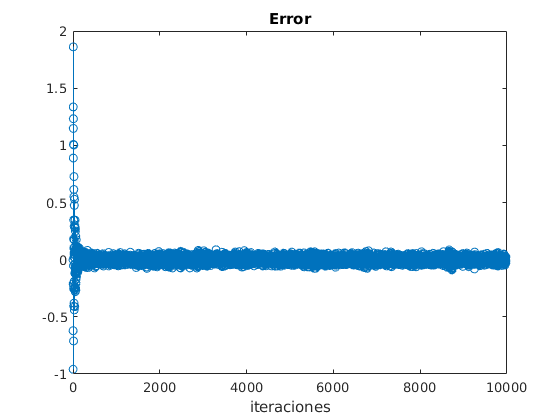

ord =20;%orden del filtro
pas = 0.0141;
%coeficientes iniciales = 0
w=zeros(1,ord);
%Proceso de Adaptación del filtro
err=zeros(1,N-ord);
for i=1:N-ord
    u=xnr(i:i+ord-1);
    y_t=w*u';%producto punto
    err(i)=xn(i)-y_t;
    w=w+pas*err(i)*xnr(i:i+ord-1);
end
figure()
stem(err)
xlabel('iteraciones')
title('Error')

Análisis del resultado

Comparación entre señal con ruido vs señal original, es decir el ruido introducido artificialmente

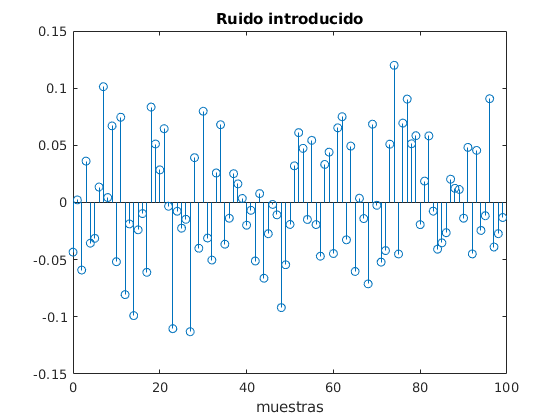

xdif=xn-xnr;
figure
stem(n(1:100),xdif(1:100))
xlabel('muestras')
title('Ruido introducido')

Comparación entre señal filtrada vs señal original. Note el transitorio del filtro cuya duración depende del número de coeficientes del filtro

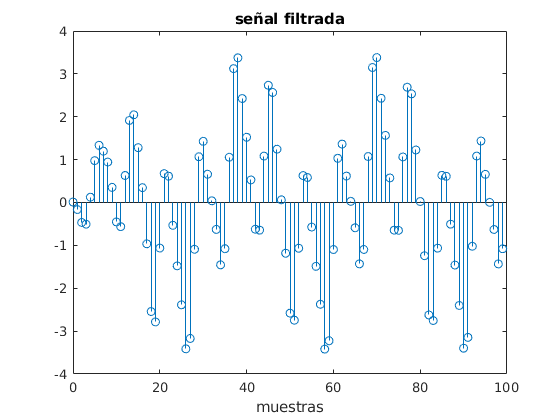

yn=filter(w,1,xnr);
figure
stem(n(1:100),yn(1:100))
xlabel('muestras')
title('señal filtrada')

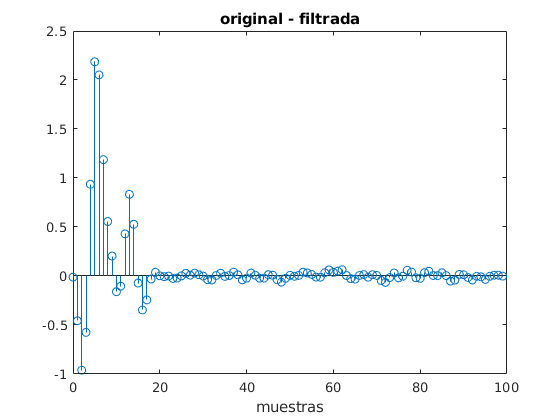

fdif=xn-yn;
figure
stem(n(1:100),fdif(1:100))
xlabel('muestras')
title('original - filtrada')

Aplicación de medidas cuantitativas de calidad eliminando el transitorio del filtro

p_pre=psnr(xnr(ord:end),xn(ord:end),max(xn))

p_pre = 36.4758

p_pos=psnr(yn(ord:end),xn(ord:end),max(xn))

p_pos = 41.7671